addpath('Utility_functions')
set(0, 'DefaultAxesFontName', 'Times New Roman');
set(0, 'DefaultTextFontName', 'Times New Roman');

folder = '..\..\Data\collagen10.20';

files = dir(folder);
files = files(3:end);
filesfmc = files([1 2 3 4 9 10 11 12]);
filesrayline = files([5 6 7 8 13 14 15 16]);

load("..\..\Data\USclutterdata\L22_14systeminfo.mat")
xs = ((-(Trans.numelements/2 -1):(Trans.numelements/2))-0.5)*Trans.spacingMm;
fs = Receive(1).decimSampleRate;
dt = 1/fs;
dz = dt*1.48/2;

% delays = [0.41 0.4 0.41 0.40 0.38 0.4 0.4; ...
%     0.37 0.39 0.40 0.39 0.39 0.36 0.41]
delay = 0.0;
% delays = [0.3472 0.3472 0 0 0 0];

irms = cell(8,1);
rms = cell(8,2);
tic;
delays = [0.3392 0.3392 0.32736 0.32736 0.37088 0.37088 0.38272 0.38272];
for i=1:8
    S = load(fullfile(folder,filesfmc(i).name));
    irm = RFtoRM(S.RcvData,S.Receive);
    irm = circshift(irm,-floor(delays(i)/dz),3);
    irms{i} = irm;
    % rm = FMCtoFocused_frequency(irm,1.48,Receive,Trans,8,5,'a_shrink','boxcar');
    rm = FMCtoFocused_time(irm,1.48,Receive,Trans,8,5,'a_shrink','boxcar');
    rms{i,1} = rm;
end

nelems = 15

nelems = 15

nelems = 15

nelems = 15

nelems = 15

nelems = 15

nelems = 15

nelems = 15

% delays = [0 0 0 0 0 0 0 0];
for i=1:8
    S = load(fullfile(folder,filesrayline(i).name));
    rm = RFtoRM(S.RcvData,S.Receive);
    rm = circshift(rm,-floor(delays(i)/dz),3);
    rms{i,2} = rm;
end
t = toc;
t/60

ans = 6.0950


len = length(irms{4});
ts = dt*(0:(len-1));
zs = 1.48*ts/2;
labels1 = {'coccollagen1023','coccollagen150','cocwater1023','cocwater150','glasscollagen1023','glasscollagen150','glasswater1023','glasswater150'};




rfnums = [1 2 1.4 9];
% rfnums = [12]
beamformed = cell(8,2,length(rfnums));      % material; rayline dry, rayline wet, safb dry, safb wet; rfnums
wb = waitbar(0);
counter = 0;
total = 8*2*4;
noise = zeros(2,2,4); %first is fmc/rayline, second is highgain/lowgain, then rfnums
for i=1:8
    for j=1:2
        for k=1:length(rfnums)
            counter = counter+1;
            waitbar(counter/total,wb)
            rm = rms{i,j};
            [das_data,~,~] = das(rm,0,1.48,Trans,Receive,8,rfnums(k),'a_shrink','boxcar');
            beamformed{i,j,k} = das_data(:,1:len);
            bmode = 20*log10(abs(das_data)+1);
            elems = 64 + (-40:40);
            if i==1 || i==3 || i==5 || i==7
                noise(j,1,k) = noise(j,1,k)+ mean(mean(bmode(elems,200:400)))/4;
            else
                noise(j,2,k) = noise(j,2,k)+ mean(mean(bmode(elems,200:400)))/4;
            end
        end
    end
end

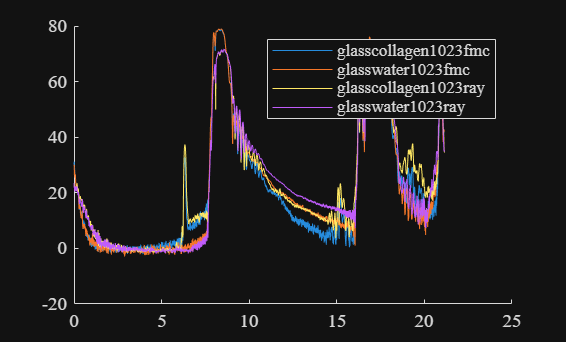

figure()
hold on
% subset = [1 3];
subset = [5 7];
k=2;
for j=1:2
    for i=subset
        das_data = beamformed{i,j,k};
        bmode = 20*log10(abs(das_data)+1);
        elems = 64 + (-20:20);
        aveprofile = mean(bmode(elems,:),1);
        plot(zs,aveprofile - noise(j,2-mod(i,2),k))   
    end
end
% labelsfmc = arrayfun(@(j) [labels1{j} 'fmc'],1:8,'UniformOutput',false)
% labelsray = arrayfun(@(j) [labels1{j} 'ray'],1:8,'UniformOutput',false)
legend([arrayfun(@(j) [labels1{j} 'fmc'],subset,'UniformOutput',false) arrayfun(@(j) [labels1{j} 'ray'],subset,'UniformOutput',false)])
hold off

labels1

labels1 = 1×8 cell array
    {'coccollagen1023'}    {'coccollagen150'}    {'cocwater1023'}    {'cocwater150'}    {'glasscollagen1023'}    {'glasscollagen150'}    {'glasswater1023'}    {'glasswater150'}


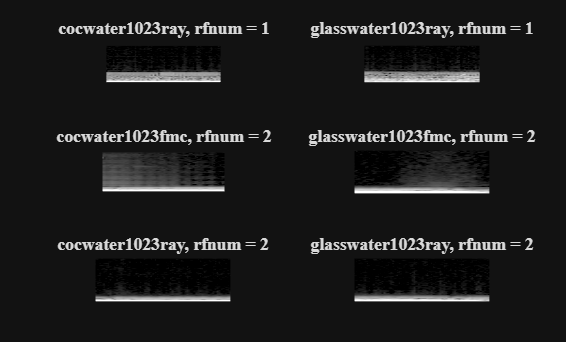


maskzs = zs > 6 & zs < 8;
maskxs = xs > (-100) & xs < (100);
pairs = [3 2 1; 7 2 1; 3 1 2; 7 1 2; 3 2 2; 7 2 2];
% maskxs = xs > (2-1) & xs < (2+1);
tiledlayout(length(pairs)/2,2);
for p=1:length(pairs)
    nexttile;
    i = pairs(p,1); j = pairs(p,2); k=pairs(p,3);
    if i==7
        maskxs = xs >= (0) & xs <= (max(xs));
    else
        maskxs = xs >= (min(xs)+1) & xs <= (0+1);
    end
    % i = 3; %file
    % j = 1; %fmc or ray
    % k = 1; %rfnum
    % normie = 60/max(max(20*log10(abs(squeeze(beamformed{i,j,k}(maskxs,maskzs)))+1)'-noise(j,2-mod(i,2),k)));
    xsinterp = linspace(min(xs(maskxs)),max(xs(maskxs)),1000);
    [X,Z] = meshgrid(xs(maskxs),zs(maskzs));
    [Xi,Zi] = meshgrid(xsinterp,zs(maskzs));

    bmode_interp = interp2(X,Z,20*log10(abs(squeeze(beamformed{i,j,k}(maskxs,maskzs)))+1).'-noise(j,2-mod(i,2),k),Xi,Zi);

    % imagesc(xs(maskxs),zs(maskzs),20*log10(abs(squeeze(beamformed{i,j,k}(maskxs,maskzs)))+1)'-noise(j,2-mod(i,2),k),[1 60])
    imagesc(squeeze(Xi(1,:)),squeeze(Zi(:,1)),bmode_interp,[1 60])
    
    colormap gray
    axis equal
    axis off
    % colorbar
    if j==1
        title([labels1{i} 'fmc, rfnum = ' num2str(rfnums(k))])
    else
        title([labels1{i} 'ray, rfnum = ' num2str(rfnums(k))])
    end
end

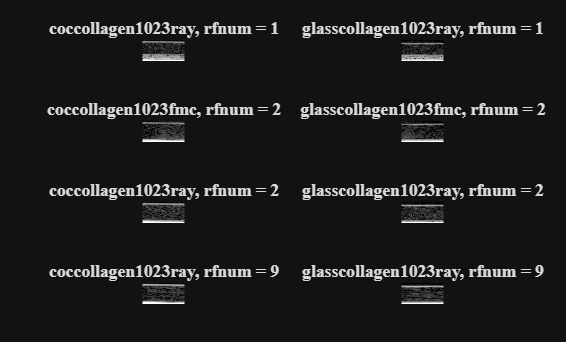

maskzs = zs > 6 & zs < 8;
maskxs = xs > (-2) & xs < (2);
pairs = [1 2 1; 5 2 1; 1 1 2; 5 1 2; 1 2 2; 5 2 2; 1 2 4; 5 2 4];
% maskxs = xs > (2-1) & xs < (2+1);
tiledlayout(length(pairs)/2,2);
for p=1:length(pairs)
    nexttile;
    i = pairs(p,1); j = pairs(p,2); k=pairs(p,3);
    % i = 3; %file
    % j = 1; %fmc or ray
    % k = 1; %rfnum
    % normie = 60/max(max(20*log10(abs(squeeze(beamformed{i,j,k}(maskxs,maskzs)))+1)'-noise(j,2-mod(i,2),k)));
    xsinterp = linspace(min(xs(maskxs)),max(xs(maskxs)),128*2);
    % xsinterp = xs(maskxs);
    % zsinterp = linspace(min(zs(maskzs)),max(zs(maskzs)),1000);
    zsinterp = zs(maskzs);
    [X,Z] = meshgrid(xs(maskxs),zs(maskzs));
    [Xi,Zi] = meshgrid(xsinterp,zsinterp);

    % bmode_interp = interp2(X,Z,20*log10(abs(squeeze(beamformed{i,j,k}(maskxs,maskzs)))+1).'-noise(j,2-mod(i,2),k),Xi,Zi,"cubic");
    imagesc(xs(maskxs),zs(maskzs),20*log10(abs(squeeze(beamformed{i,j,k}(maskxs,maskzs)))+1)'-noise(j,2-mod(i,2),k),[1 60])
    % imagesc(squeeze(Xi(1,:)),squeeze(Zi(:,1)),bmode_interp,[1 60])
    colormap gray
    axis equal
    axis off
    % colorbar
    if j==1
        title([labels1{i} 'fmc, rfnum = ' num2str(rfnums(k))])
    else
        title([labels1{i} 'ray, rfnum = ' num2str(rfnums(k))])
    end
end

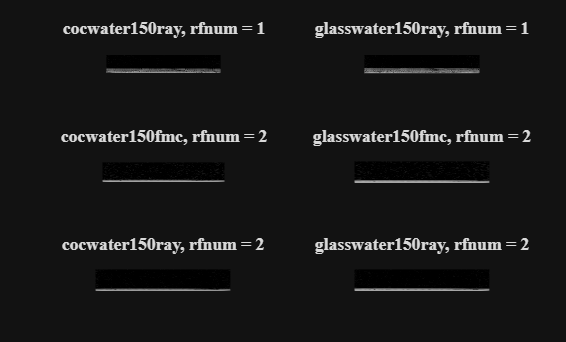

maskzs = zs > 6 & zs < 8;
maskxs = xs > (-100) & xs < (100);
pairs = [4 2 1; 8 2 1; 4 1 2; 8 1 2; 4 2 2; 8 2 2];
% maskxs = xs > (2-1) & xs < (2+1);
tiledlayout(length(pairs)/2,2);
for p=1:length(pairs)
    nexttile;
    i = pairs(p,1); j = pairs(p,2); k=pairs(p,3);
    % i = 3; %file
    % j = 1; %fmc or ray
    % k = 1; %rfnum
    % normie = 60/max(max(20*log10(abs(squeeze(beamformed{i,j,k}(maskxs,maskzs)))+1)'-noise(j,2-mod(i,2),k)));
    xsinterp = linspace(min(xs(maskxs)),max(xs(maskxs)),1000);
    [X,Z] = meshgrid(xs(maskxs),zs(maskzs));
    [Xi,Zi] = meshgrid(xsinterp,zs(maskzs));

    bmode_interp = interp2(X,Z,20*log10(abs(squeeze(beamformed{i,j,k}(maskxs,maskzs)))+1).'-noise(j,2-mod(i,2),k),Xi,Zi);

    % imagesc(xs(maskxs),zs(maskzs),20*log10(abs(squeeze(beamformed{i,j,k}(maskxs,maskzs)))+1)'-noise(j,2-mod(i,2),k),[1 60])
    imagesc(squeeze(Xi(1,:)),squeeze(Zi(:,1)),bmode_interp,[1 60])
    
    colormap gray
    axis equal
    axis off
    % colorbar
    if j==1
        title([labels1{i} 'fmc, rfnum = ' num2str(rfnums(k))])
    else
        title([labels1{i} 'ray, rfnum = ' num2str(rfnums(k))])
    end
end

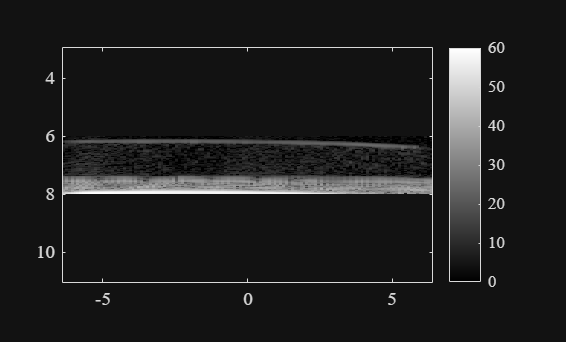

figure()
maskzs = zs > 6 & zs < 8;
maskxs = xs > (-100) & xs < (100);
% maskxs = xs > (2-1) & xs < (2+1);
i = 1; %file
k = 1; %fmc or ray
normie = 60/max(max(20*log10(abs(squeeze(beamformed{i,k}(maskxs,maskzs)))+1)'-noise(k,1)));
imagesc(xs(maskxs),zs(maskzs),normie*(20*log10(abs(squeeze(beamformed{i,k}(maskxs,maskzs)))+1)'-noise(k,1)),[0 60])
colormap gray
axis equal
% axis off
colorbar

% title(labels{i})

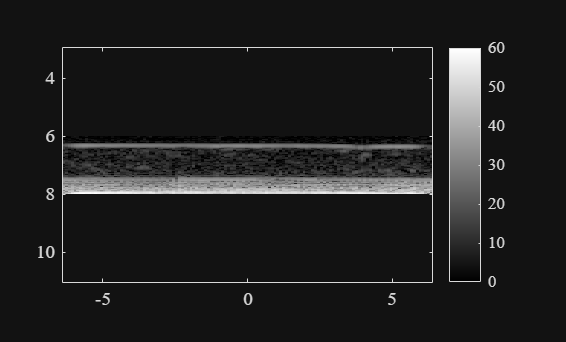

maskzs = zs > 6 & zs < 8;
maskxs = xs > (-100) & xs < (100);
% maskxs = xs > (2-1) & xs < (2+1);
i = 5; %file
k = 2; %fmc or ray
normie = 60/max(max(20*log10(abs(squeeze(beamformed{i,k}(maskxs,maskzs)))+1)'-noise(k,1)));
imagesc(xs(maskxs),zs(maskzs),normie*(20*log10(abs(squeeze(beamformed{i,k}(maskxs,maskzs)))+1)'-noise(k,1)),[0 60])
colormap gray
axis equal
% axis off
colorbar

% title(labels{i})

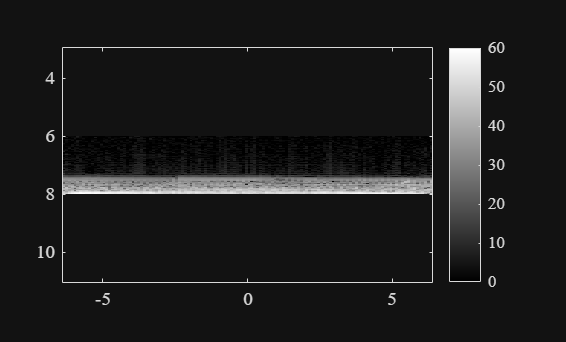

maskzs = zs > 6 & zs < 8;
maskxs = xs > (-100) & xs < (100);
% maskxs = xs > (2-1) & xs < (2+1);
i = 7; %file
k = 2; %fmc or ray
normie = 60/max(max(20*log10(abs(squeeze(beamformed{i,k}(maskxs,maskzs)))+1)'-noise(k,1)));
imagesc(xs(maskxs),zs(maskzs),normie*(20*log10(abs(squeeze(beamformed{i,k}(maskxs,maskzs)))+1)'-noise(k,1)),[0 60])
colormap gray
axis equal
% axis off
colorbar

% title(labels{i})

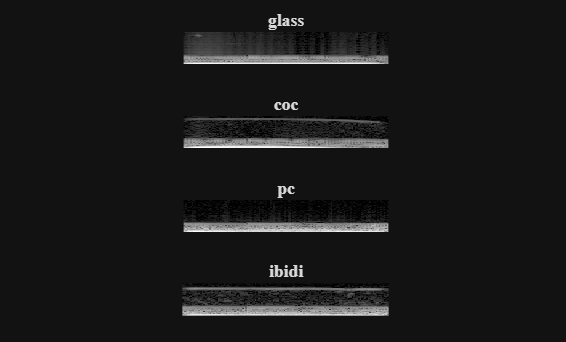

figure()
tiledlayout(4,1,'TileSpacing', 'Compact', 'Padding', 'Compact');
maskzs = zs > 6 & zs < 8;
maskxs = xs > (-100) & xs < (100);
% maskxs = xs > (2-1) & xs < (2+1);
pairs = [3 1 ; 1 1 ; 7 2; 5 2];
for p=1:4
    i = pairs(p,1); k = pairs(p,2);
    nexttile;
    normie = 60/max(max(20*log10(abs(squeeze(beamformed{i,k}(maskxs,maskzs)))+1)'-noise(k,1)));
    imagesc(xs(maskxs),zs(maskzs),normie*(20*log10(abs(squeeze(beamformed{i,k}(maskxs,maskzs)))+1)'-noise(k,1)),[0 60])
    colormap gray
    axis equal
    axis off
    % colorbar
    title(labels{i})
end

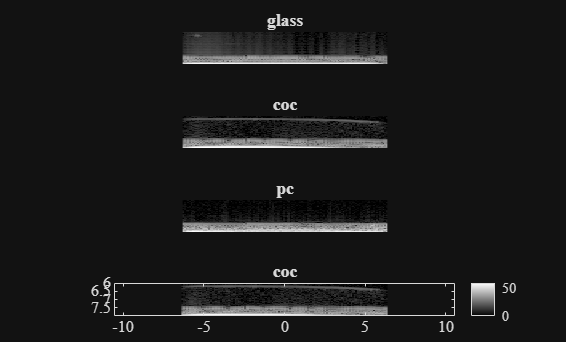

maskzs = zs > 6 & zs < 8;
maskxs = xs > (-100) & xs < (100);
% maskxs = xs > (2-1) & xs < (2+1);
i = 1; %file
k = 1; %fmc or ray
normie = 60/max(max(20*log10(abs(squeeze(beamformed{i,k}(maskxs,maskzs)))+1)'-noise(k,1)));
imagesc(xs(maskxs),zs(maskzs),normie*(20*log10(abs(squeeze(beamformed{i,k}(maskxs,maskzs)))+1)'-noise(k,1)),[0 60])
colormap gray
axis equal
% axis off
colorbar
title(labels{i})

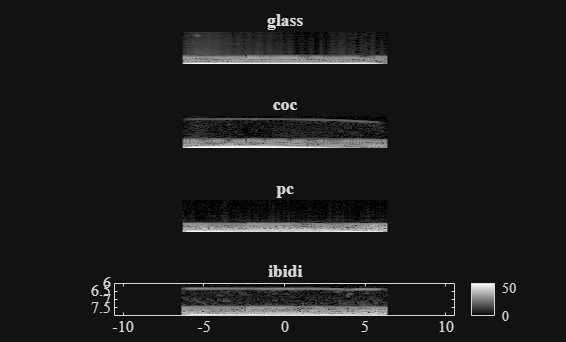

maskzs = zs > 6 & zs < 8;
maskxs = xs > (-100) & xs < (100);
% maskxs = xs > (2-1) & xs < (2+1);
i = 5; %file
k = 2; %fmc or ray
normie = 60/max(max(20*log10(abs(squeeze(beamformed{i,k}(maskxs,maskzs)))+1)'-noise(k,1)));
imagesc(xs(maskxs),zs(maskzs),normie*(20*log10(abs(squeeze(beamformed{i,k}(maskxs,maskzs)))+1)'-noise(k,1)),[0 60])
colormap gray
axis equal
% axis off
colorbar
title(labels{i})

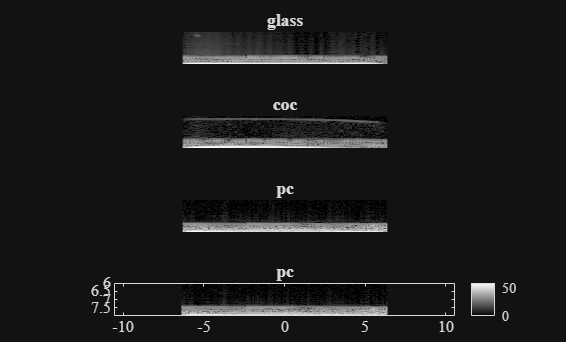

maskzs = zs > 6 & zs < 8;
maskxs = xs > (-100) & xs < (100);
% maskxs = xs > (2-1) & xs < (2+1);
i = 7; %file
k = 2; %fmc or ray
normie = 60/max(max(20*log10(abs(squeeze(beamformed{i,k}(maskxs,maskzs)))+1)'-noise(k,1)));
imagesc(xs(maskxs),zs(maskzs),normie*(20*log10(abs(squeeze(beamformed{i,k}(maskxs,maskzs)))+1)'-noise(k,1)),[0 60])
colormap gray
axis equal
% axis off
colorbar
title(labels{i})

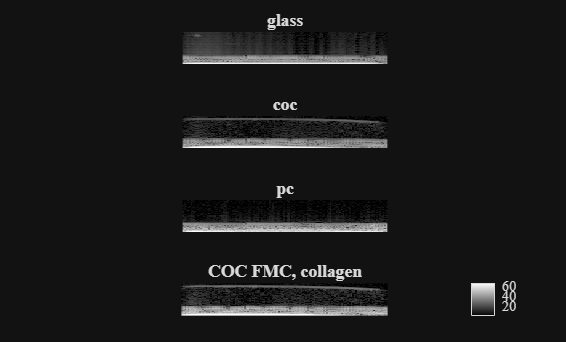

% maskxs = xs > (4.5-1) & xs < (4.5+1);
imagesc(xs(maskxs),zs(maskzs),20*log10(abs(squeeze(beamformed{1,1}(maskxs,maskzs)))+1)'-noise(1,1),[1 66])
colormap gray
axis equal
axis off
title('COC FMC, collagen')
colorbar

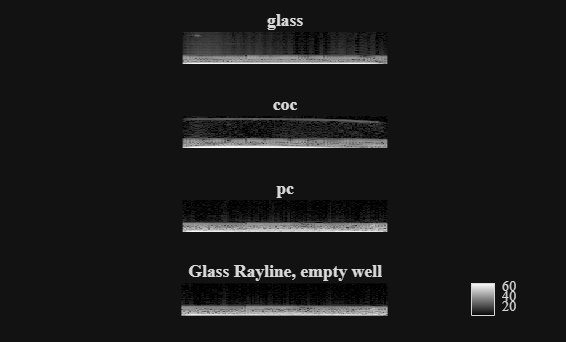

imagesc(xs(maskxs),zs(maskzs),20*log10(abs(squeeze(beamformed{7,2}(maskxs,maskzs)))+1)'-noise(2,1),[1 66])
colormap gray
axis equal
axis off
title('Glass Rayline, empty well')
colorbar

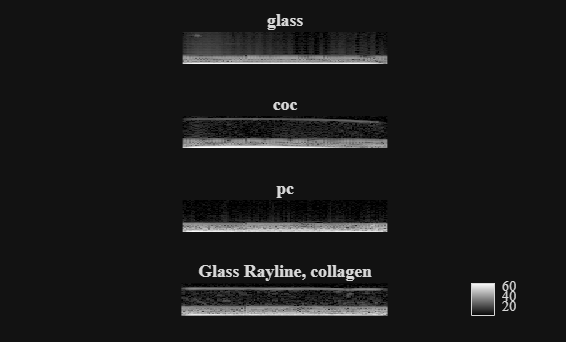

imagesc(xs(maskxs),zs(maskzs),20*log10(abs(squeeze(beamformed{5,2}(maskxs,maskzs)))+1)'-noise(2,1),[1 66])
colormap gray
axis equal
axis off
title('Glass Rayline, collagen')
colorbar


labels1 = {'coccollagen1023','coccollagen150','cocwater1023','cocwater150','glasscollagen1023','glasscollagen150','glasswater1023','glasswater150'};
figure()
hold on
lab = 1;
subset = [4 8];
for k=2
for i=subset
% figure()
das_data = beamformed{i,k};
% if i==4
%     das_data = beamformed{i,1};
% else
%     das_data = beamformed{i,2};
% end
elems = 110 + (-10:10);
% elems = 64;
ave = zeros(len,1);
for j=elems
    ave = ave + 20*log10(abs(squeeze(das_data(j,1:len)))'+1);
end
ave = ave / length(elems);
mean(ave(100:500))
% if i==4
%     plot(zs(1:len),ave-0.7851)
% else
%     plot(zs(1:len),ave-3.0545)
% end
plot(zs(1:len),ave)
% title(labels{lab})
lab=lab+1;
end
end

ans = 2.4943

ans = 2.4881

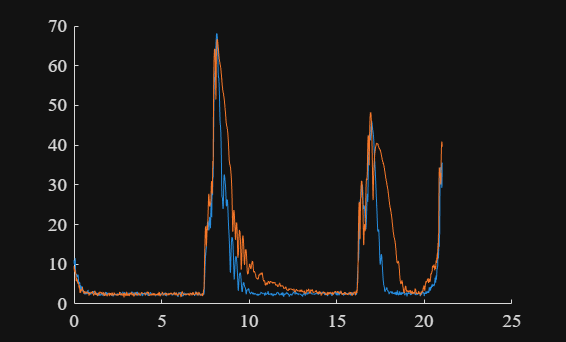

hold off


% legend(labels1(subset))

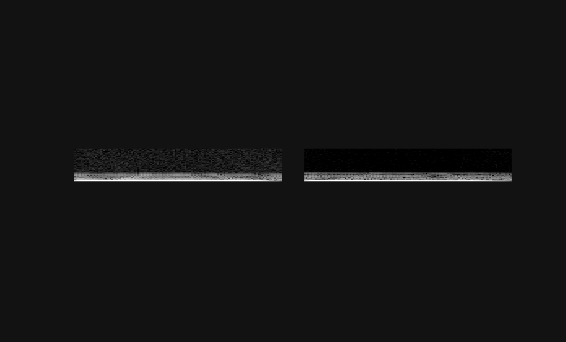

tiledlayout(1,2,'TileSpacing','tight');
nexttile;
imagesc(xs(maskxs),zs(maskzs),20*log10(abs(squeeze(beamformed{4,1}(maskxs,maskzs)))+1)'-0.7851,[0 50])
colormap gray
axis equal
axis off
nexttile;

% axis off
imagesc(xs(maskxs),zs(maskzs),20*log10(abs(squeeze(beamformed{8,2}(maskxs,maskzs)))+1)'-3.0545,[0 50])
colormap gray
axis equal
axis off

ave

ave =     9.5266
    8.9558
    8.1395
    8.8613
    8.7500
    8.6354
    8.4607
    7.6748
    7.7644
    7.7631
